**Exercise 1**

Consider the discrete random variables $X_1$ and $X_2$ with joint probability distribution


$$f\left(x_1 ,x_2 \right)=\left\lbrace \begin{array}{ll}
{\textrm{cx}}_1 x_2 , & x_1 =1,2,3,4,x_2 =1,2\\
0, & \textrm{otherwise}
\end{array}\right.,$$


where $c$ is a constant.

a) Find $c$

clear; clc; close all;

x1 = 1:4;
x2 = 1:2;

%We know that the total propability must sum to 1, hence
S1 = sum(x1);
S2 = sum(x2);
%cS1S2 = 1 => c = 1/(S1*S2)
c = 1/(S1 * S2)

c = 0.0333


%we store these in a pmf table for ease of use
P = c * (x1(:) * x2);

disp("PMF table")

PMF table


disp(array2table(P, "VariableNames", ...
    compose("X2_%d",x2), "RowNames", compose("X1_%d",x1)))

              X2_1        X2_2  
            ________    ________

    X1_1    0.033333    0.066667
    X1_2    0.066667     0.13333
    X1_3         0.1         0.2
    X1_4     0.13333     0.26667




fprintf("Total probability (check) = %.3f\n\n", sum(P, "all"));

Total probability (check) = 1.000



b) Calculate the marginal distributions $f_1(x_1)$ and $f_2(x_2)$.

%to find f1(x1) we sum over all x2
f1 = sum(P, 2);

%vice-versa for f2(x2)
f2 = sum(P, 1);


disp("f1(x1)")

f1(x1)


disp(table(x1(:), f1(:), 'VariableNames', {'x1','f1'}))

    x1    f1 
    __    ___

    1     0.1
    2     0.2
    3     0.3
    4     0.4




disp("f2(x2)")

f2(x2)


disp(table(x2(:), f2(:), 'VariableNames', {'x2','f2'}))

    x2      f2   
    __    _______

    1     0.33333
    2     0.66667



c) Calculate the conditional distributions $f(x_1|x_2)$ and $f_2(x_2|x_1)$.

% f1(x1|x2) = P(X1=x1, X2=x2) / f2(x2)
f1_given_x2 = P ./ f2;

% f2(x2|x1) = P(X1=x1, X2=x2) / f1(x1)
f2_given_x1 = P ./ f1;

disp("Conditional f1(x1|x2): columns are x2 = 1,2")

Conditional f1(x1|x2): columns are x2 = 1,2


disp(array2table(f1_given_x2, "VariableNames", ...
    compose("x2_%d",x2), "RowNames", compose("x1_%d",x1)))

            x2_1    x2_2
            ____    ____

    x1_1    0.1     0.1 
    x1_2    0.2     0.2 
    x1_3    0.3     0.3 
    x1_4    0.4     0.4 




disp("Conditional f2(x2|x1): columns are x2 = 1,2")

Conditional f2(x2|x1): columns are x2 = 1,2


disp(array2table(f2_given_x1, "VariableNames", ...
    compose("x2_%d",x2), "RowNames", compose("x1_%d",x1)))

             x2_1       x2_2  
            _______    _______

    x1_1    0.33333    0.66667
    x1_2    0.33333    0.66667
    x1_3    0.33333    0.66667
    x1_4    0.33333    0.66667



d) Find the propability $P(1\leq X_1 \leq 2, 0 \leq X_2 \leq 1)$.

%as X2 = 1,2, the condition implies X2 = 1
idx_x1 = (x1 >= 1 & x1 <= 2);
idx_x2 = (x2 >= 0 & x2 <= 1);

prob_d = sum(P(idx_x1, idx_x2), 'all');

fprintf('P(1 <= X1 <= 2, 0 <= X2 <= 1) = %.3f\n\n', prob_d);

P(1 <= X1 <= 2, 0 <= X2 <= 1) = 0.100



e) Calculate the covariance and the correlation between $X_1$ and $X_2$. Hint: Check for independence.

%expectations
EX1  = sum(x1 .* f1');
EX2  = sum(x2 .* f2);

%E[X1X2]
EX1X2 = 0;
for i = 1:length(x1)
    for j = 1:length(x2)
        EX1X2 = EX1X2 + x1(i)*x2(j)*P(i,j);
    end
end

%Variances
EX1_sq = sum((x1.^2) .* f1');
EX2_sq = sum((x2.^2) .* f2);

VarX1 = EX1_sq - EX1^2;
VarX2 = EX2_sq - EX2^2;

CovX1X2 = EX1X2 - EX1*EX2;
CorrX1X2 = CovX1X2 / sqrt(VarX1*VarX2);

fprintf("E[X1] = %.3f\n", EX1);

E[X1] = 3.000


fprintf("E[X2] = %.3f\n", EX2);

E[X2] = 1.667


fprintf("E[X1X2] = %.3f\n", EX1X2);

E[X1X2] = 5.000


fprintf("Var(X1) = %.3f\n", VarX1);

Var(X1) = 1.000


fprintf("Var(X2) = %.3f\n", VarX2);

Var(X2) = 0.222


fprintf("Cov(X1,X2) = %.3f\n", CovX1X2);

Cov(X1,X2) = -0.000


fprintf("Corr(X1,X2) = %.3f\n", CorrX1X2);

Corr(X1,X2) = -0.000


**Exercise 2**

Consider the continous random variables $X_1$ and $X_2$ with joint propability density

$f\left(x_1 ,x_2 \right)=\left\lbrace \begin{array}{ll}
c\left(x_1 +x_2 \right), & 0\le x_1 \le 1,0\le x_2 \le 1\\
0, & \textrm{otherwise}
\end{array}\right.$where $c$ is a constant.

a) Find $c$

syms x1 x2 c real

%% use sum of propabilities = 1 to find c
f = c*(x1 + x2);

I = int(int(f, x2, 0, 1), x1, 0, 1);
c_sol = solve(I == 1, c);

fprintf("c = %.3f\n", c_sol)

c = 1.000


%% Insert c into the density
f = subs(f, c, c_sol);

fprintf("f(x1,x2) = %s", f)

f(x1,x2) = x1 + x2

b) Calculate the maginal densities $f_1(x_1)$ and $f_2(x_2)$.

f1 = int(f, x2, 0, 1); %integrate out x2
f2 = int(f, x1, 0, 1); %integrate out x1

fprintf("f1(x1) = %s", f1)

f1(x1) = x1 + 1/2


fprintf("f2(x2) = %s", f2)

f2(x2) = x2 + 1/2

c) Calculate $E(X_1), E(X_2), E(X_1X_2)$ and find the covariance between $X_1$ and $X_2$.

EX1 = int(int(x1*f, x2, 0, 1), x1, 0, 1);
EX2 = int(int(x2*f, x2, 0, 1), x1, 0, 1);
EX1X2 = int(int(x1*x2*f, x2, 0, 1), x1, 0, 1);

CovX1X2 = simplify(EX1X2 - EX1*EX2);

fprintf("E[X1] = %s", EX1)

E[X1] = 7/12

fprintf("E[X2] = %s", EX2)

E[X2] = 7/12

fprintf("E[X1*X2] = %s", EX1X2)

E[X1*X2] = 1/3

fprintf("Cov(X1,X2) = %s", CovX1X2)

Cov(X1,X2) = -1/144

**Exercise 3**

Consider a manufacturing process producing balls of some alloy for use in ball bearings. Let $X_1$ be the radius of the balls and $X_2$ be the density of the alloy. Let


$$f\left(x_1 ,x_2 \right)=\left\lbrace \begin{array}{ll}
\;\frac{1}{2}+\frac{1}{2}\left(x_1 +x_2 \right), & 0\le x_1 \le 1,0\le x_2 \le 1\\
0, & \textrm{otherwise}
\end{array}\right.$$


Calculate the average weight of the balls produced.

%the ball weight is W = \rho * V = X2 * 4/3 * pi * X1^3
%the average weight is then E[W] = 4/3 pi * E[X1^3X2] so:
syms x1 x2
f = 1/2 + 1/2*(x1 + x2);

EW = int(int((4/3)*pi*x1^3*x2*f, x2, 0, 1), x1, 0, 1);
simplify(EW)

$$ans = \frac{37\,\pi }{180}$$

double(EW)

ans = 0.6458

**Exercise 4**

Consider again the situation described in Exercise 3. Suppose that the balls are within specifications if they have a radius of $0.8 \pm 0.1$. What percentage of the balls meet the specification on average

syms x1 x2
f = 1/2 + 1/2*(x1 + x2);

f1 = int(f, x2, 0, 1); % marginal of X1
p = int(f1, x1, 0.7, 0.9); % probability radius is within spec

simplify(f1)

$$ans = \frac{x_{1}}{2}+\frac{3}{4}$$

simplify(p)

$$ans = \frac{23}{100}$$

**Exercise 5**

Consider the data set `UStemps.txt`. The data set contains 56 observations of the average temperature in January of cities in the USA together with their longitude and latitude. Use MATLAB (or what you prefer) to produce a scatter plot of temperature versus longitude, a scatter plot of temperature versus latitude and a (3-dimensional) scatter plot of temperature versus longitude and latitude. Find the correlation between temperature and longitude and the correlation between temperature and latitude. Comment on your results. The relevant functions in MATLAB are `plot()`, `plot3()` and `corrcoef ()`.

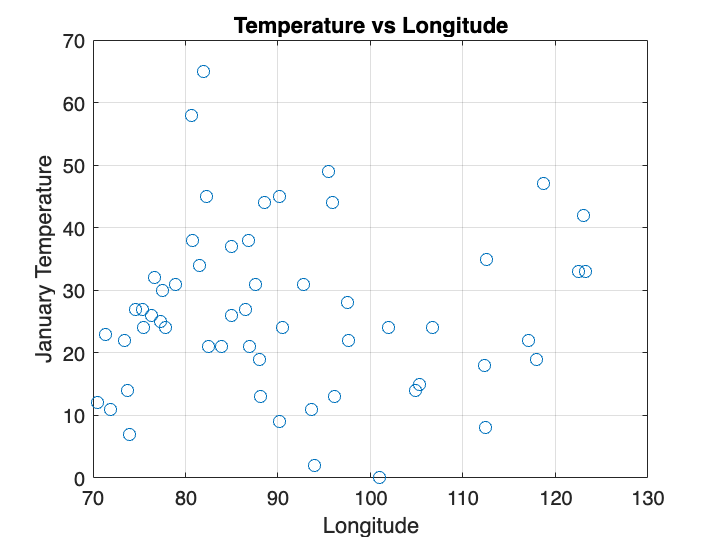

%get data
T = readtable("data/UStemps.txt");

temp = T.JanTemp;
lat  = T.Lat;
lon  = T.Long;

%temperature vs longitude scatter
figure
plot(lon, temp, "o")
xlabel("Longitude")
ylabel("January Temperature")
title("Temperature vs Longitude")
grid on

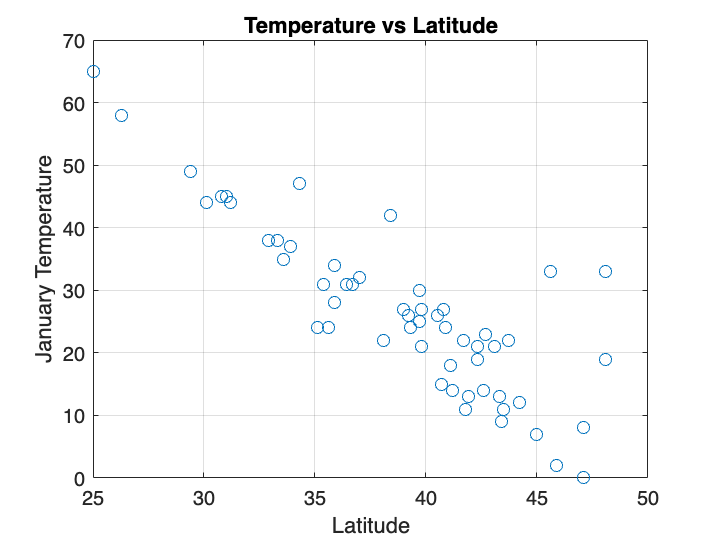


%temperature vs latitude scatter
figure
plot(lat, temp, "o")
xlabel("Latitude")
ylabel("January Temperature")
title("Temperature vs Latitude")
grid on

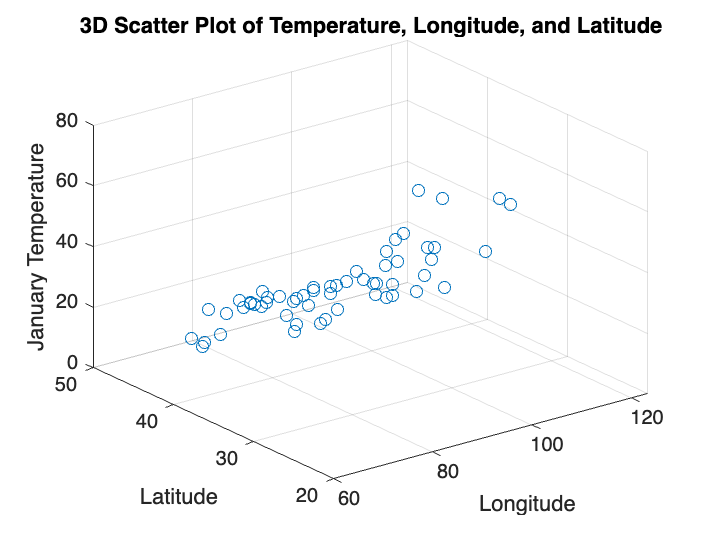


%temperature vs longitude and latitude 3d scatter
figure
plot3(lon, lat, temp, "o")
xlabel("Longitude")
ylabel("Latitude")
zlabel("January Temperature")
title("3D Scatter Plot of Temperature, Longitude, and Latitude")
grid on


%correlations
C_temp_lon = corrcoef(temp, lon);
C_temp_lat = corrcoef(temp, lat);

corr_temp_lon = C_temp_lon(1,2);
corr_temp_lat = C_temp_lat(1,2);

fprintf("Correlation between temperature and longitude: %.3f\n", corr_temp_lon);

Correlation between temperature and longitude: 0.024


fprintf("Correlation between temperature and latitude:  %.3f\n", corr_temp_lat);

Correlation between temperature and latitude:  -0.848


**Exercise 6**

Consider independent random variables $X_1$ and $X_2$ with normal probability densities $f_1(x_1; 0, 1)$, $f_2(x_2; 0, 9)$ and let $X_3 = X_1 - X_2$. Calculate the covariance and correlation between $X_1$ and $X_3$ and between $X_2$ and $X_3$. Simulate a sample $X_{1,s}$, $X_{2,s}$ of size $n = 100$ for each of the random variables $X_1$ and $X_2$ and calculate $X_{3,s} = X_{1,s} - X_{2,s}$. Produce a scatter plot of $X_{3,s}$ versus $X_{1,s}$ and a scatter plot of $X_{3,s}$ versus $X_{2,s}$. Find the sample correlation between $X_{1,s}$ and $X_{3,s}$ and between $X_{2,s}$ and $X_{3,s}$. Comment on the difference of the absolute values of the correlations.

%Theoretical values
varX1 = 1;
varX2 = 9;
varX3 = varX1 + varX2; %var(x-y) = var(x) + var(y) - 2 cov(x,y) -- As variables are independent cov = 0

%cov(x, y+z) = cov(x,y) + cov(y,z)
%cov(X1, X3) = cov(X1,X1-X2) = cov(X1,X1) - cov(X1,X2) = var(X1)
cov_X1_X3 = varX1;

%cov(X2, X1-X2) = cov(X2,X1) - var(X2)
cov_X2_X3 = - varX2;

rho_X1_X3 = cov_X1_X3 / (sqrt(varX1)*sqrt(varX3));
rho_X2_X3 = cov_X2_X3 / (sqrt(varX2)*sqrt(varX3));

fprintf("Theoretical covariance cov(X1,X3) = %.4f\n", cov_X1_X3);

Theoretical covariance cov(X1,X3) = 1.0000


fprintf("Theoretical covariance cov(X2,X3) = %.4f\n", cov_X2_X3);

Theoretical covariance cov(X2,X3) = -9.0000


fprintf("Theoretical correlation rho(X1,X3) = %.4f\n", rho_X1_X3);

Theoretical correlation rho(X1,X3) = 0.3162


fprintf("Theoretical correlation rho(X2,X3) = %.4f\n", rho_X2_X3);

Theoretical correlation rho(X2,X3) = -0.9487



%Simulated sample
n = 100;

X1s = randn(n,1); %N(0,1)
X2s = 3 * randn(n,1); %N(0,9) as std = 3
X3s = X1s - X2s;

%sample correlations
R13 = corrcoef(X1s, X3s); %returns 2x2 matrix
R23 = corrcoef(X2s, X3s); %2x2 matrix

sample_rho_X1_X3 = R13(1,2); %extract actual coefficient from matrix
sample_rho_X2_X3 = R23(1,2);

fprintf('\nSample correlation corr(X1s,X3s) = %.4f\n', sample_rho_X1_X3);


Sample correlation corr(X1s,X3s) = 0.3647


fprintf('Sample correlation corr(X2s,X3s) = %.4f\n', sample_rho_X2_X3);

Sample correlation corr(X2s,X3s) = -0.9580


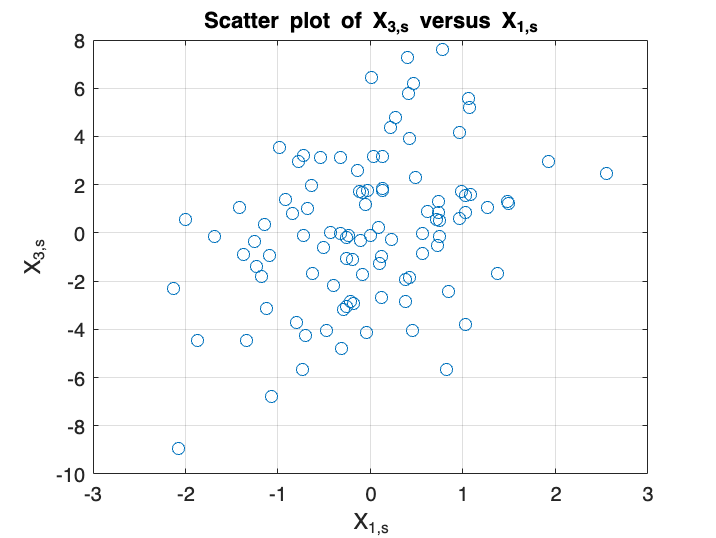


%% Scatter plot: X3s versus X1s
figure;
plot(X1s, X3s, 'o');
xlabel('X_{1,s}');
ylabel('X_{3,s}');
title('Scatter plot of X_{3,s} versus X_{1,s}');
grid on;

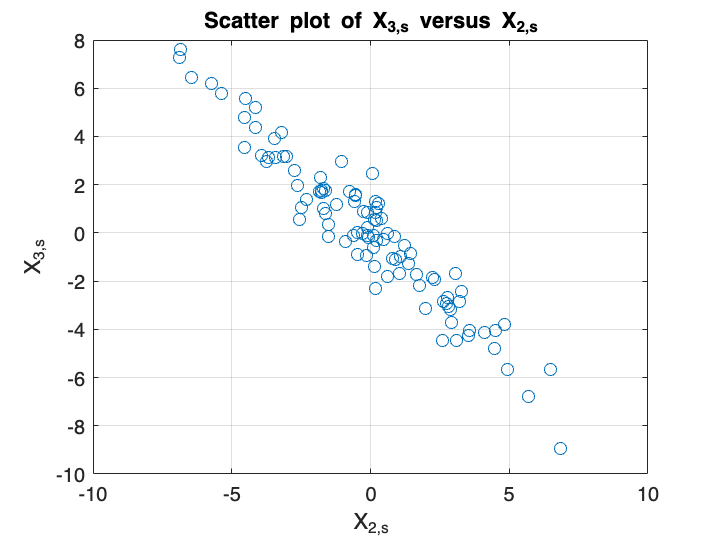


%% Scatter plot: X3s versus X2s
figure;
plot(X2s, X3s, 'o');
xlabel('X_{2,s}');
ylabel('X_{3,s}');
title('Scatter plot of X_{3,s} versus X_{2,s}');
grid on;

**Exercise 7**

Use the definition of expectations to show that


$$\left.E\left(\left(X_1 -\mu_1 \right.\right)\left(X_2 -\mu_2 \right)\right)=E\left(X_1 X_2 \right)-\mu_1 \mu_2 ,$$


where $\mu_1=E(X_1)$ and $\mu_2 = E(X_2)$ and $X_1$ and $X_2$ are continuous random variables with joint propability density $f(x_1, x_2)$.

We start with


$$E\left(\left(X_1 -\mu_1 \right)\left(X_2 -\mu_2 \right)\right)=E\left(X_1 X_2 -\mu_2 X_1 -\mu_1 X_2 +\mu_1 \mu_2 \right)$$



$$E\left(X_1 X_2 \right)-\mu_2 E\left(X_1 \right)-\mu_1 E\left(X_2 \right)+\mu_1 \mu_2 E\left(1\right)=E\left(X_1 X_2 \right)-\mu_2 \mu_1 -\mu_1 \mu_2 +\mu_1 \mu_2 =E\left(X_1 X_2 \right)-\mu_1 \mu_2$$


**Exercise 8**

Let $X_1$ and $X_2$ be random variables such that


$$X_2 ={a\;X}_1 +b$$


where $a\neq 0$ and $b$ are constants. Calculate the correlation $\rho$.

As $\rho = 1$ describes a perfect positive linear relation and $\rho = -1$ describes a perfectly negative linear relation $\rho$ must either equal 1 or -1 depending on the sign of $a$.